# Laboratory 2

hop = @(hr,hf)(1/(1+hr*hf));

hf = tf(1,[2 1])

hf =
 
     1
  -------
  2 s + 1
 
Continuous-time transfer function.



hr1 = 2

hr1 = 2

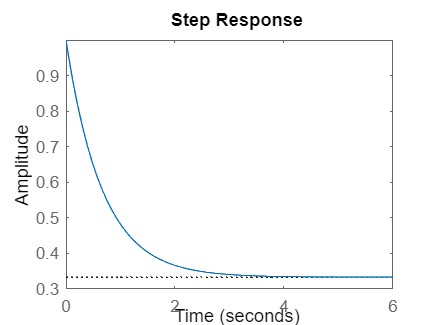

step(hop(hf,hr1))

stepinfo(hop(hf,hr1))

ans = struct with fields:
         RiseTime: 0
    TransientTime: 2.6080
     SettlingTime: 3.0701
      SettlingMin: 0.3334
      SettlingMax: 1
        Overshoot: 200.0000
       Undershoot: 0
             Peak: 1
         PeakTime: 0



hr2 = tf(2,[1 0])

hr2 =
 
  2
  -
  s
 
Continuous-time transfer function.



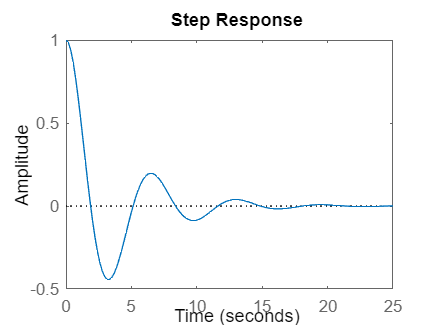

step(hop(hf,hr2))

stepinfo(hop(hf,hr2))

ans = struct with fields:
         RiseTime: 0
    TransientTime: 14.1159
     SettlingTime: NaN
      SettlingMin: -0.4432
      SettlingMax: 1
        Overshoot: Inf
       Undershoot: Inf
             Peak: 1
         PeakTime: 0



hr3 = tf(2,[1 0 0])

hr3 =
 
   2
  ---
  s^2
 
Continuous-time transfer function.



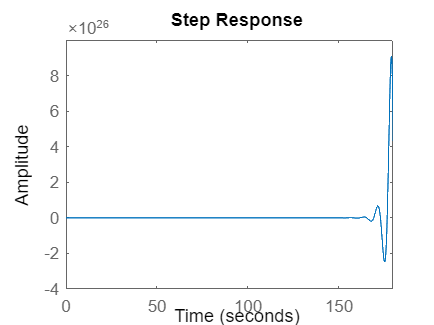

step(hop(hf,hr3))

stepinfo(hop(hf,hr3))

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf
